# ***Chapter 7 - Time Series Analysis***

## *Section A: Time Series and Stationarity*

A ***time series*** is a sequence of measurements recorded at regular time intervals. A time series can be denoted in the compact form of $\{x_t\}_{t=1}^T$ , or in an expanded form of $x_1,...,x_T$. A measurement could be mutli-dimensional readings or a one-dimensional value. In this chapter, we only consider the case when $x_t$ is of one dimension, i.e.,  when $x_1,...,x_T$ is a *univariate time series*.

**Comment**: In quantitative research, we are dealing with all sorts of data which are structured as a time series, e.g., stock daily prices, trading volumes, macroeconomic data; even those more qualititative type of information are wrapped as a time series first for consumption, e.g., an array of 1/0s where 1(0) is when there is (isn't) a Fed meeting held in that month. Fair to say, time series analysis is the most basic tool a quant should master at. 

The foundation of time series analysis is ***stationarity***.

A time series $\{x_t\}$ is ***strictly stationary*** if for any set of time points $(t_1,t_2,...,t_k)$ and an arbitrary integer $h,$ the joint distribution of $(x_{t_1},x_{t_2},...,x_{t_k})$ is identifcal to that of $(x_{t_1+h},x_{t_2+h},...,x_{t_k+h})$, i.e., the joint distribution of $(x_{t_1},x_{t_2},...,x_{t_k})$ is invariant under time shift.

Example: an i.i.d. random variable time series is strictly stationary, but the converse statement is not true: e.g., say$\{x_t\}$ is i.i.d., $\{x_t+x_{t+1}\}$ is then strictly stationary but not i.i.d.

The above defition of stationarity is too restrictive. In practice, a weaker version of stationarity is often assumed. 

A time series $\{x_t\}$ is ***weakly stationary ***if it satisfies the following properties:

1)  $E(x_t)=\mu$, which is a constant, i.e., the mean of $x_t$ is time-invariant,

2)  $Cov(x_t,x_{t-h})=\gamma_h$, which only depends on $h$, and is called the lag-$h$ autocovariance of $x_t$. And we know: $\gamma_0=Var(x_t)$ and $\gamma_h=\gamma_{-h}$.

Note: the definition implicitily assume the first two moments of $x_t$ are finite if it's weakly stationary. A strictly stationary time series with finite first two moments are weakly stationary, but the converse is not true in general.

An example of weakly stationary time series which is not strictly stationay: let $\{z_t\}$ be i.i.d. time series where $ {z_t \tilde}$N(0,1), a time series $\{x_t\}$ is defined as $x_t=z_t$ if $t$ is an even number, $x_t=\frac{1}{\sqrt{2}}(z_{t-1}^2-1)$ if $t $ is an odd number.

The weak stationarity implies that the time plot of data versus $t$ would show that those values $x_t$ fluctuate with constant variation around a constant level. Therefore, *t**he first step in time series analysis is always plot the data*: non-stationary patterns such as trend, seasonality, heteroskedasticity would emerge naturally if existent. 

In the following, we are mainly concerned with weak stationarity.

## *Section B: Decomposition of A Time Series*

The two typical non-stationary patterns in a time series are trend and seasonality. Decomposition helps describe the two components embedded in a time series. Decomposition could also isolate other components such as cyclicality, holiday effects, etc. Here we focus on the most common decomposition procedure which aims to estimate time series trend and seasonality.

In decomposition, we need to separate trend and seasonal components from the underlying stationary innovation time series. Smoothing method such as moving average smoothing or regression-based smoothing are usually implemented to identify the trend component. Seasonal component is relatively easy to isolate as long as there exists strong evidence (from extra analysis or from experience-based knowledge) on the cycle length of the seasonal effect. The remaining one after neutralizing for seasonality and trend is the random component, which is more likely to be stationary (though need further tests). 

#### Additive Decomposition: $x_t$*= Trend + Seasonal + Random*

#### Multiplicative Decomposition: $x_t$*= Trend x Seasonal x Random*

A multiplicative model can be transformed to an additive one by taking logarithm on boths sides of the equation (given all positive observations). Curved trend and/or non-constant seasonal variations usually imply a multiplicative model; and time series in dollar unit such as those of stock prices, company revenues are more likely in multiplicative form. In the following we explain the decomposition procedure for an additive model through an example.

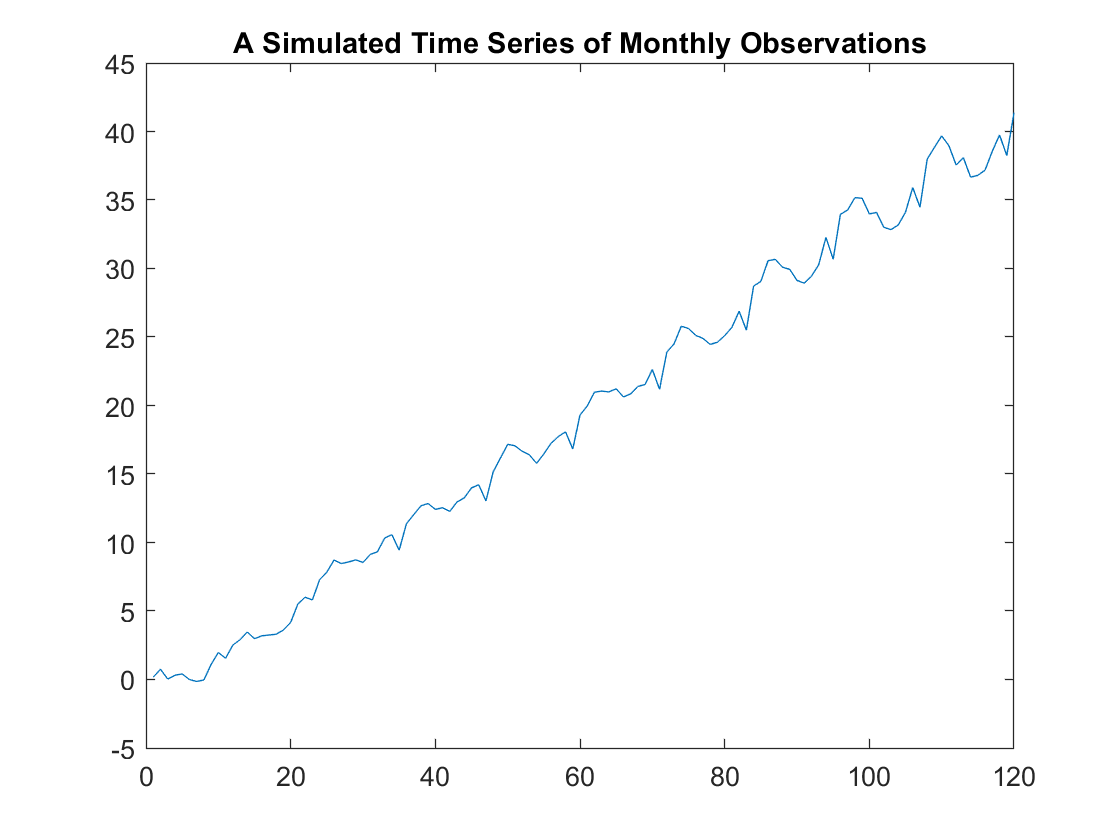

%%%%%%%%%%%%%%% Simulate a time series following the additive structure %%%%%%%%
%   specify a model with treand and seasonality
Mdl_ma1 = arima('D',1,'Seasonality',12,'Variance',0.1,'Constant',0);

%   simulate a time series of observations for the model
rng(0); % for reproducibility
T=120;
x_ts=simulate(Mdl_ma1,T);

%   always plot the time series first (**** Rule of Thumb *****)
figure
plot(x_ts)
title('A Simulated Time Series of Monthly Observations')

#### Isolation of Trend

To decompose the time series, we need to estimate the trend component first. There are two main approaches:

- Moving Average

- Regression-Based Smoothing

To calculate the **moving average**, a time span needs to be specified. For instance, for time span of 5, the moving average estimate $\hat{x}_t$ at time t is:

$\hat{x}_t=(x_{t-2}+x_{t-1}+x_t+x_{t+1}+x_{t+2})/5$. 

However, if we know in advance there exists a seasonal componet, we need to use the seasonal span for the moving average calculation. The seasonal span is 4 for quarterly observations and we have:

$\hat{x}_t=\frac{1}{8}x_{t-2}+\frac{1}{4}x_{t-1}+\frac{1}{4}x_{t}+\frac{1}{4}x_{t+1}+\frac{1}{8}x_{t+2}$. 

The seasonal span is 12 for monthly observations and we have:

$\hat{x}_t=\frac{1}{24}x_{t-6}+\frac{1}{12}x_{t-5}+\frac{1}{12}x_{t-4}+...+\frac{1}{12}x_{t+4}+\frac{1}{12}x_{t+5}+\frac{1}{24}x_{t+6}$. 

The most-oftenly used **regression-based smoothing** is LOESS (locally weighted linear least regression using 2nd degree polynoimal). It requires a time span parameter, based on which it calculates the weights for observations around the interested time point. And then run weighted least square to fit the data within the time span window. Details of LOESS see[ here](https://www.mathworks.com/help/curvefit/smoothing-data.html#bq_6ys3-3). 

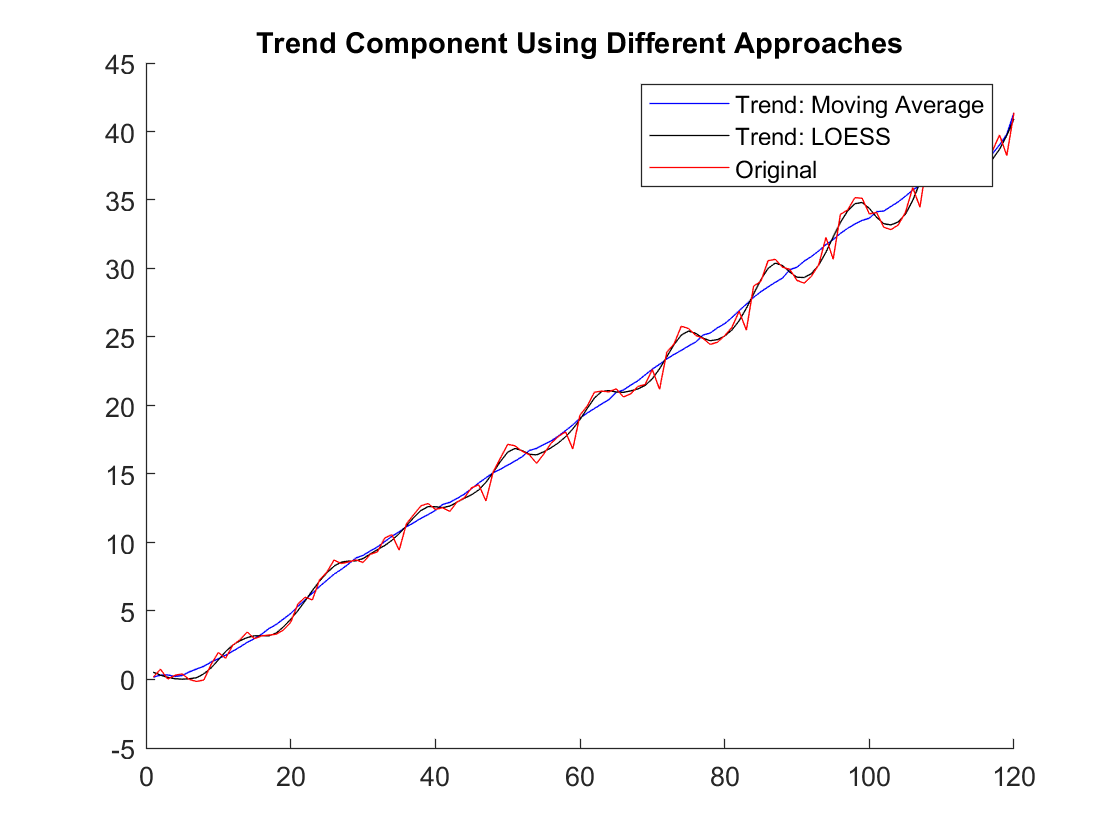

% we'll use the matlab function directly to identify the trend component

%  moving average
trend_ma=smooth(x_ts,12,'moving');

%   loess
trend_loess=smooth(x_ts,12,'loess');

figure
hold on
p(1)=plot(trend_ma,'b');
p(2)=plot(trend_loess,'k'); 
p(3)=plot(x_ts,'r');
legend({'Trend: Moving Average','Trend: LOESS','Original'});
title('Trend Component Using Different Approaches');

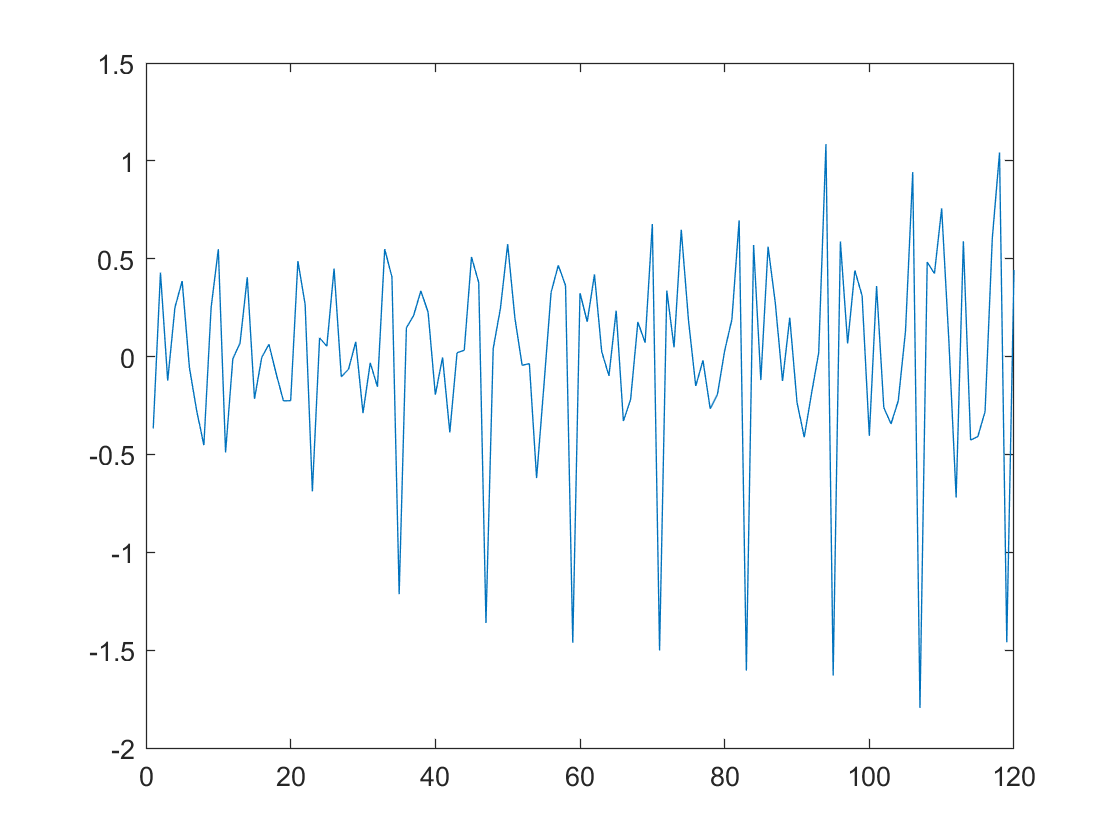

figure
plot(x_ts-trend_loess)

#### Isolation of seasonal effect 

In the example, we assume it's a time series of monthly observations with seasonality, which entails estimating monthly effect for each month of the year: Jan, Feb, ..., Dec. It's relative easy to isolate the monthly effect, which only requires calculation of average de-trended observations for each month. 

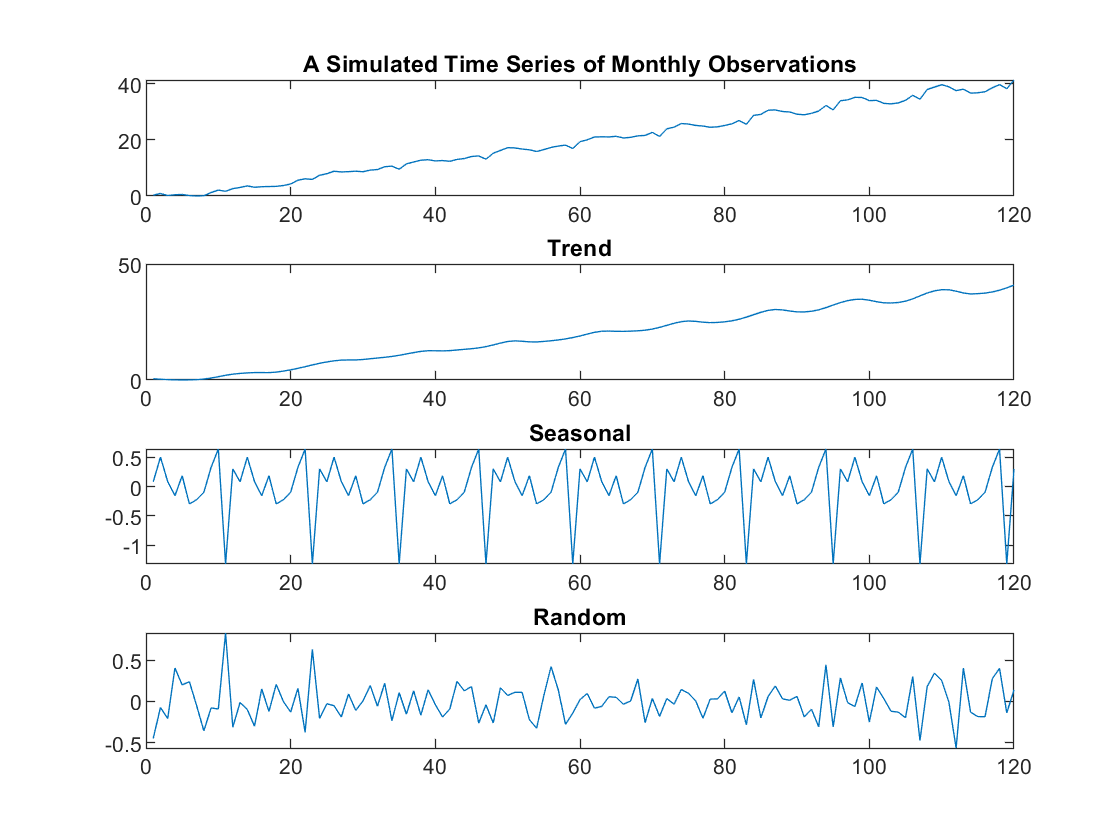

%   assuming we use the LOESS for the trend component
x_ts_trend=trend_loess;

%   calculate monthly averages of de-trended observations
monthly_avg=nan(1,12);
for i=1:12
    monthly_avg(i)=mean(x_ts(i:12:end)-x_ts_trend(i:12:end));
end

%   construct the time series of seasonal component only
x_ts_seasonal=nan(T,1);
for t=1:length(x_ts)
    
    %   month number
    tmp_num=mod(t,12);
    if tmp_num==0
        tmp_num=12;
    end
    
    %   assign monthly average to the seasonal time series
    x_ts_seasonal(t)=monthly_avg(tmp_num);
end

%   the random component is what's left after removing trend and seasonal
%   effect
x_ts_random=x_ts-x_ts_trend-x_ts_seasonal;

%   plot the original, trend, seasonal component and the remaining random
%   component
figure
subplot(4,1,1)
plot(x_ts)
title('A Simulated Time Series of Monthly Observations')
subplot(4,1,2)
plot(x_ts_trend)
title('Trend')
subplot(4,1,3)
plot(x_ts_seasonal)
title('Seasonal')
subplot(4,1,4)
plot(x_ts_random)
title('Random')
%   the random component looks like a stationary time series

%   at least no obvious trend or seaonality are exhibited 

%   let's do some simple tests for stationarity

%   Augmented Dickey-Fuller Test for unit root (trendy data has a unit root)
%   null hypothesis: unit root exists
[h,p]=adftest(x_ts) % h=0: can't reject the null hypo
[h,p]=adftest(x_ts_random) % h=0: reject the null hypo

h = logical
   0


p = 0.9990

%   using Two-sample Kolmogorov-Smirnov test 

h = logical
   1


p = 1.0000e-03

%   null hypothesis: the two samples are from the same distribution
%  (this is indeed to test strict stationarity, however, if a time
%   series is not weakly stationary, the test very likely would reject the
%   null hypothesis)
[h,p]=kstest2(x_ts(1:T/2),x_ts(T/2+1:T)) % h=1: reject the null hypo
[h,p]=kstest2(x_ts_random(1:T/2),x_ts_random(T/2+1:T)) % h=1: reject the null hypo

h = logical
   1


p = 7.8241e-28

h = logical
   0


p = 0.6289

## *Section C: ACF and PACF*

Autocorrelation function (ACF) and partial autocorrelation function (PACF) are important attributes when analyze a time series

**Definition of Autocorrelation Function (ACF):** the ACF of a time series $\{x_t\}$ gives correlation between $x_t $ and $x_{t-h}$ for any positive integer $h$. For a stationary time series, those autocorrelations are invariant under $t$, and are functions of lag $h$ only. 

*Theoretical ACF* for a stationary time series*: *

$\rho_h=Corr(x_t,x_{t-h})=\frac{\gamma_h}{\gamma_0}$, for $h=0,1,2,...$,  where $\gamma_h$ is the autocovariance at lag $h$, and $\gamma_0$ is the variance of the time series.

*Sample ACF* for any time series: 

$\hat{\rho_h}=\frac{\sum_{t=h+1}^T(x_t-\overline{x})(x_{t-h}-\overline{x})}{\sum_{t=1}^T(x_t-\overline{x})^2}$,  for $h=0,1,2,...$, where $\overline{x}$ is the sample mean of all the observations. (why not adjusted for T-h, a good answer [here](https://stats.stackexchange.com/questions/56238/question-about-sample-autocovariance-function)).

Sample autocorrelations are estimates for theoretical autocorrelations.

The standard error for the lag $h$ sample autocorrelation $\hat{\rho_h}$ is:

$SE(\hat{\rho_h})\approx\sqrt{(1+\sum_{i=1}^{h-1}\hat{\rho_i}^2)/T}$, if the time series has moving average order of $h-1$ (Bartlett, 1946);

$SE(\hat{\rho_h})=\sqrt{\frac{(T-h)}{(T+2)}\frac{1}{T}}$, if the time series is white noise (Box and Jenkins, 1976).

Therefore, when $h<<T$ and $\rho_i$'s are sufficiently small, we can use $\frac{1}{\sqrt{T}}$ as approximate standard error, which leads to $\pm\frac{2}{\sqrt{T}$ as bounds for 95% confidence level. 

**Definition of Partial Autocorrelation Function (PACF):** the PACF of a time series $\{x_t\}$ gives *conditional correlation* between $x_t $ and $x_{t-h}$ for any positive integer $h$ after taking into account their linear dependencies on $x_{t-1},x_{t-2},..,x_{t-h+1}$. For a stationary time series, those conditional autocorrelations are invariant under $t$, and are functions of lag $h$ only. 

*Theoretical PACF* for a stationary time series*: *

$\phi_{h,h}=\frac{Cov(x_t,x_{t-h} | x_{t-1},...,x_{t-h+1})}{\sqrt{Var(x_t| x_{t-1},...,x_{t-h+1})Var(x_{t-h}| x_{t-1},...,x_{t-h+1})}}$, for $h=1,2,...$

*Sample PACF* for any time series can be calculated using two methods,

**Method 1**: Linear Regression 

For each lag $h$, we need to run the linear regression: $x_t=\mu_h+\hat{\phi_{h,1}}x_{t-1}+\hat{\phi_{h,2}}x_{t-2}+...+\hat{\phi_{h,h}}x_{t-h}+e_t$, and  $\hat{\phi_{h,h}}$ is the sample partial autocorrelation at lag $h$.

**Method 2**: Durbin-Levinson Recursion 


$$\left(\begin{array}{cccc}
\hat{\rho_0} & \hat{\rho_1}  & \cdots &\hat{\rho_{h-1}} \\
\hat{\rho_1} &\hat{\rho_0} & \cdots & \hat{\rho_{h-2}} \\
\vdots & \vdots & \vdots & \vdots \\
\hat{\rho_{h-1}}&\hat{\rho_{h-2}} & \cdots &\hat{\rho_0} \\
\end{array}\right)
\left(\begin{array}{c}
\hat{\phi_{h,1}} \\
\hat{\phi_{h,2} }\\
\vdots \\
\hat{\phi_{h,h} }\\
\end{array}\right)
= 
\left(\begin{array}{c}
\hat{\rho_1} \\
\hat{\rho_2} \\
\vdots \\
\hat{\rho_h} \\
\end{array}\right) \,
$$


where $\hat{\rho_i}$, $i=0,...,h$ are the sample autocorrelations. This is called the Yule-Walker equation.

## *Section D: AR(1) Model and MA(1) Model*

Before introducing the generalized framework of ARIMA (Autoregressive Integrated Moving Average) models, let's make sure we know well the properties of the two simplest (but most informative and applicable) models: the first-order autoregressive model, a.k.a, AR(1); and the first-order moving average model, a.k.a, MA(1). Solid understanding of both models paves the way for applying some model calibration technics for general time series.

### AR(1) Model: $x_t=\delta+\phi_1x_{t-1}+w_t$

*Assumptions for AR(1)*

- $w_t \overset{iid}{\sim} N(0, \sigma^2_w)$, the errors/innovations are iid normal random variables with mean of 0 and a constant variance of $\sigma_w^2$.

- $\{x_t\}$ is (weakly) stationary. **We'll see this implies **$|\phi_1|<1$**.**

*Comment*: in ARIMA models, we usually assume normal distributions for errors (or called innovations) for the convenience of making statistical inference and estimating model paramters. The normality assumption in most applications is sufficiently robust for data analysis. However, practitioners may also assume non-normal distributed innovations if necessary. 

*Theoretical properties for AR(1)*

- $E(x_t)=\frac{\delta}{1-\phi_1}$, this gives the theoretical mean of this stationary time series

- $Var(x_t)=\frac{\sigma_w^2}{1-\phi_1^2}$, therefore, $|\phi_1|<1$ is required for the variance to be well-defined

- theoretical autocorelations are $\rho_h=\phi_1^h, \forall h>=0$.

- theoretical partial autocorrelations are $\phi_{h,h}=\phi_1$ for $h=1$, otherwise 0 for $h>1$.

%   define an AR model: x_t=2+0.7*x_{t-1}+w_t, where w_t\tilde N(0,0.5)
phi1=0.7;

Mdl_ar1 =   arima with properties:

     Description: "ARIMA(1,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 0
        Constant: 2
              AR: {0.7} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.5

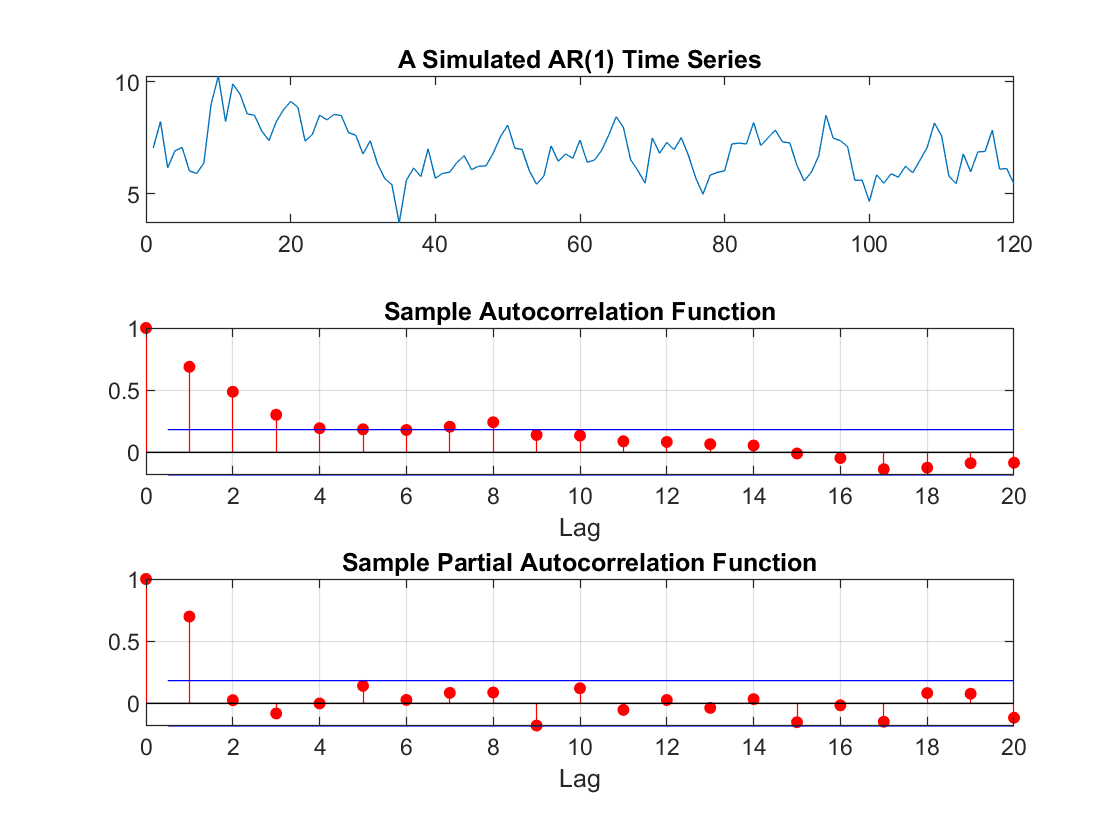

Mdl_ar1 = arima('Constant',2,'AR',{phi1},'ARLags',1,'Variance',0.5)
%   simulate a time series which has the above structure
T=120;
rng(0); %  reproducibility
ar1_ts=simulate(Mdl_ar1,T);

%   generate sample ACF and PACF plots along with the time series
subplot(3,1,1)
plot(ar1_ts)
title('A Simulated AR(1) Time Series');
subplot(3,1,2)
autocorr(ar1_ts)
ylabel([])
subplot(3,1,3)
parcorr(ar1_ts)

ylabel([])

Mdl_ma1 =   arima with properties:

     Description: "ARIMA(0,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 1
        Constant: 1
              AR: {}
             SAR: {}
              MA: {0.9} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1

In AR(1) model, for a positive value of $\phi_1$, the ACF exponentially decreases to 0 as the lag *h* increases.  For negative, the ACF also exponentially decays to 0 as the lag increases, but the algebraic signs for the autocorrelations alternate between positive and negative.

For an AR model, the theoretical PACF “shuts off” past the order of the model (easy to prove). In AR(1) model, the theoretical PACF are all 0 for the lag number greater than 1. Put another way, the number of non-zero partial autocorrelations gives the order of the AR model.  

If we extend observations for general AR models, their ACF and PACF would typically have the following characteristics:

- ACF tapers off exponentially;

- PACF shuts off past certain order, which gives an estimate of the order of the AR model.

### MA(1) Model: $x_t=\mu+w_t+\theta_1w_{t-1}$

*Assumptions for MA(1)*

- $w_t \overset{iid}{\sim} N(0, \sigma^2_w)$, the errors/innovations are independently identically distributed normal random variables with mean of 0 and a constant variance of $\sigma_w^2$.

**We also assume the absolute value of **$\theta_1$** is less than 1 **to satisfy a restriction called *invertibility****,*** which is always programmed in softwares when estimate coefficients for MA models. An MA model is ***invertible*** if it can be transformed to an equivalent converging infinite order AR model.  

*Theoretical properties for MA(1)*

- 
$$E(x_t)=\mu$$


- 
$$Var(x_t)=(1+\theta_1^2)\sigma_w^2$$


- theoretical autocorelations are $\rho_1=\frac{\theta_1}{1+\theta_1^2}$, and $\rho_h=0$ for $h>1$

- theoretical partial autocorrelations can be derived from Yule-Walker equations: $\phi_{h,h}=\frac{(-1)^{h+1}\theta_1^h}{1+\theta_1^2+...+\theta_1^{2h}}$ for $h\geq1$.

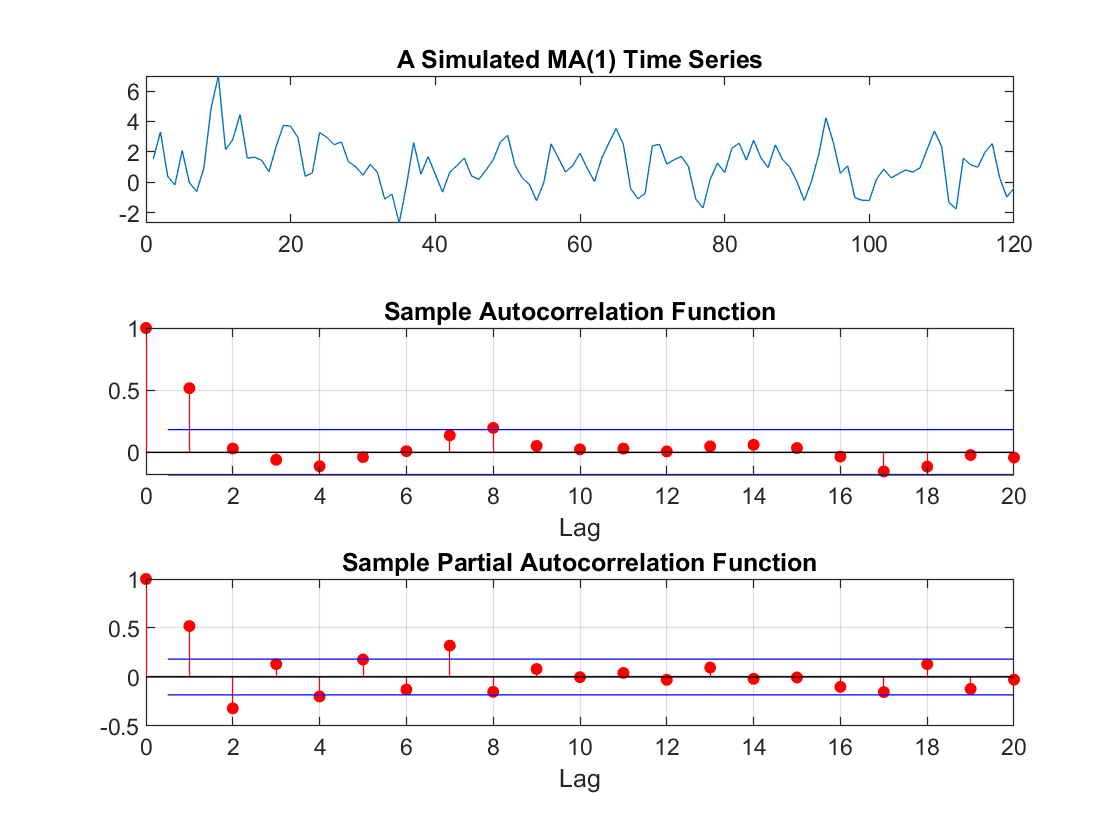

%   define an MA model: x_t=1+w_t+0.9*w_{t-1}, where w_t\tilde N(0,1)
theta1=0.9;
Mdl_ma1 = arima('Constant',1,'MA',{theta1},'MALags',1,'Variance',1)
%   simulate a time series which has the above structure
T=120;
rng(0); %  reproducibility
ma1_ts=simulate(Mdl_ma1,T);

%   generate sample ACF and PACF plots along with the time series
subplot(3,1,1)
plot(ma1_ts)
title('A Simulated MA(1) Time Series');
subplot(3,1,2)
autocorr(ma1_ts)

ylabel([])
subplot(3,1,3)
parcorr(ma1_ts)
ylabel([])

For a MA model, the theoretical ACF shuts off past the order of the model. In the above example of MA(1), we see a clear spike at lag 1 in sample ACF plot, although there seem exist a significant autocorrelation at lag 8, which is a false positive observation given we know the structure of the time series beforehand. In the MA(1) model, theoretical PACF alternatively decayes to zero. For MA(q) model, 

- ACF shuts off past the model order of q

- PACF tapers off exponentially

### Parameter Estimation and Residual Diagnostics 

We'll focus on the following two models for this section, although the ideas are the same for general ARMA models.

- AR(1) Model: $x_t=\delta+\phi_1x_{t-1}+w_t$

- MA(1) Model: $x_t=\mu+w_t+\theta_1w_{t-1}$

Maximum Likelihood Estimation (MLE) can be used to calibrate parameters for general ARMA model with Gaussian innovations. Ordinary least squares method (Gaussian innovations only) and Yule-Walker equation (moment-based method, more general) can be used to estimate parameters for a pure AR model. For pure MA models, Durbin's method, also called two-state regression, is one of the most widely used techniques. 

In the following example, we'll step-by-step go through the model estimation procedure followed with necesary diagonostic tests for fitted model. We'll use the example of AR(1) time series only.

%%%%%%%%%%%%%%%%%%%%%%%%%%
%   now we already have two simulated time series: one for AR(1) and one
%   for MA(1). Assuming we don't know the parameters of the two models, but
%   their model structures have been specified, i.e., AR(1) and MA(1)
%   respectively, let's try to estimate the parameters for each model
%%%%%%%%%%%%%%%%%%%%%%%%%%

%   the AR(1) time series: ar1_ts
%   The structure is: x_t=2+0.7*x_{t-1}+w_t, where w_t\tilde N(0,0.5),
%   we'll try to estimate those parameters given only time series

%   let's specify the structure of the model AR(1)

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     1.6735       0.34868         4.7994      1.5912e-06
    AR{1}        0.7388      0.053603         13.783      3.2364e-43
    Variance    0.43489      0.052664         8.2578      1.4832e-16



ToEstMdl=arima(1,0,0);

%   fit the model structure with observed time series to estimate
%   paramters
EstMdl_ar1=estimate(ToEstMdl,ar1_ts);

The estimated parameter values are all very close to their true values with statististical significances. To evaluate whether it's a 'good' model, we need to test whether the residual time series $\{\hat{w_t}\}$ is white noise process or not, i.e., the process of **residual diagnostics:**

- The residuals are normally distributed: e.g., through normality tests.

- The residuals have mean of 0: e.g., through t-test.

- The residuals have constant variance: e.g., through heteroscedasticity tests.

- The residuals are un-correlated: e.g., ACF and PACF, and [the Ljung-Box test.](https://en.wikipedia.org/wiki/Ljung%E2%80%93Box_test)

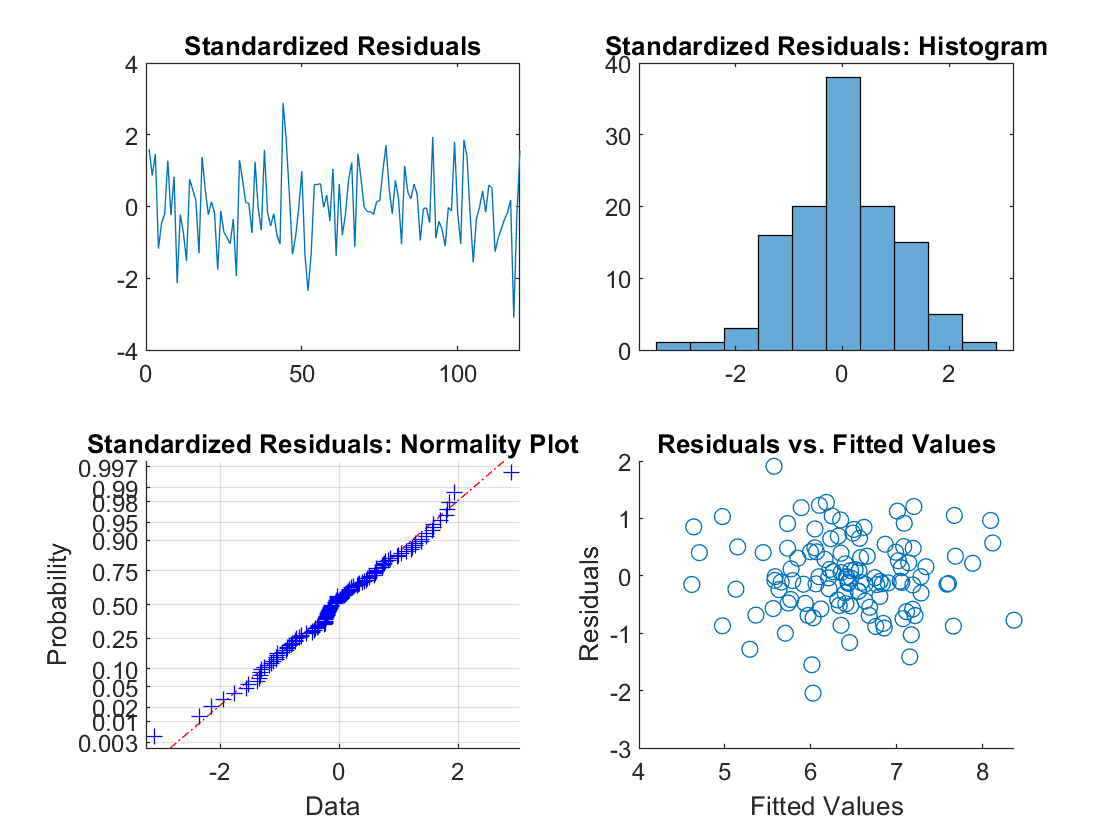

%   infer model residuals 
[res,blah,logL]=infer(EstMdl_ar1,ar1_ts);

%   fitted values
ar1_ts_fitted=ar1_ts-res;

%   let's perform residual diagnostics

%   standardized residuals
res_std = res/sqrt(EstMdl_ar1.Variance);

%   generate figures for normality tests and non-constant variance
figure
subplot(2,2,1)
plot(res_std)
title('Standardized Residuals')
subplot(2,2,2)
histogram(res_std,10)
title('Standardized Residuals: Histogram')

subplot(2,2,3)
normplot(res_std)
title('Standardized Residuals: Normality Plot')

h = 0

p = 0.5000

subplot(2,2,4)
scatter(ar1_ts_fitted,res);
xlabel('Fitted Values');
ylabel('Residuals');
title('Residuals vs. Fitted Values')

h = 0

p = 0.9149

%   Jarque-Bera test for normality
%   null hypothesis: the sample is normally distributed
[h,p]=jbtest(res_std)

h = logical
   0


p = 0.7381

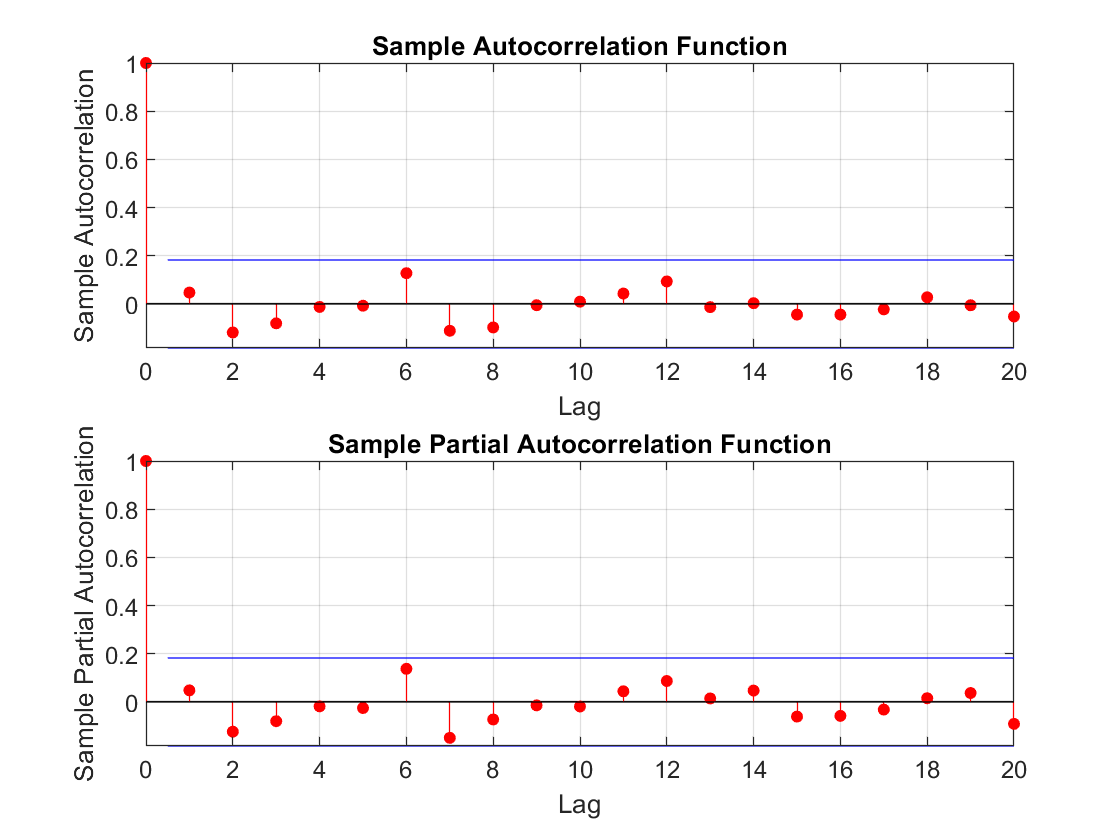


%   t-test for mean
%   null hypothesis: the sample is from a normal distribution with mean 0
%   and unknown variance
[h,p]=ttest(res_std)
%   Engle test for residual heteroscedasticity

%   null hypothesis: no conditional heteroscedasticity
[h,p]=archtest(res_std)
%   generate ACF and PACF, and Ljung-Box Test
figure

h = logical
   0


pValue = 0.9610

subplot(2,1,1)
autocorr(res_std)

h = logical
   1


pValue = 7.0055e-14

subplot(2,1,2)
parcorr(res_std)
%   Ljung-Box Q test
%   null hypothesis: there exist no autocorrleations in the residual time
%   series
[h,pValue] = lbqtest(res)
%   if we test the original data you'll see it rejects with p=0 
[h,pValue] = lbqtest(ar1_ts)

We can't find strong evidences which invalidates the fitted model through residual diagnostics, which is expected since we know the structure of the model in advance. Let's introduce the model selection criteria before move to ARIMA model. 

%   we'll fit the original time series to four different models:
%   AR(1),AR(2), MA(1), MA(2)
%   and choose the best one based on information criteria (AIC and BIC)
EstMdl1 = arima('ARLags',1);
EstMdl2 = arima('ARLags',1:2);
EstMdl3 = arima('MALags',1);
EstMdl4 = arima('MALags',1:2);

% Preallocate loglikelihood vector

aic =   246.6264
  247.3396
  278.5160
  261.4349


bic =   254.9889
  258.4895
  286.8785
  272.5849


logL = zeros(4,1); 
[~,~,logL(1)] = estimate(EstMdl1,ar1_ts,'Display','off');
[~,~,logL(2)] = estimate(EstMdl2,ar1_ts,'Display','off');
[~,~,logL(3)] = estimate(EstMdl3,ar1_ts,'Display','off');
[~,~,logL(4)] = estimate(EstMdl4,ar1_ts,'Display','off');

%   information criteria
[aic,bic] = aicbic(logL, [3; 4; 3; 4], length(ar1_ts)*ones(4,1))

The lower IC values, the better. We see both AIC and BIC point to AR(1) as the best model for the time series.

## *Section E: Identifying An ARIMA Model *

We'll go through applicable rules that help us identify an ARIMA model. We start with defining a sesaonal ARIMA model, which is a more general form and is capable of estimating seasonal effects. 

Notation for a seasonal ARIMA model: $ARIMA(p,d,q)\times(P,D,Q)S$.

where: 

- *p* = non-seasonal AR order, *d* = non-seasonal differencing order, *q* = non-seasonal MA order

- *P* = seasonal AR order, *D* = seasonal differencing order, *Q* = seasonal MA order

- *S* = time span of repeating seasonal patterns.

When not considering differencing operations ($d=0$ and $D=0)$, a time series $\{x_t\}$ with mean $\mu$ of this model can be written as follows (using the backshift operator $B$):

$\Phi_s(B^S)\Phi(B)(x_t-\mu)=\Theta_s(B^S)\Theta(B)w_t$, 

where:

- the non-seasonal AR component: $\Phi(B)=1-\phi_1B-...-\phi_pB^p$

- the non-seasonal MA component: $\Theta(B)=1+\theta_1B+...+\theta_qB^q$

- the seasonal AR (SAR) component:  $\Phi_s(B)=1-\varphi_1B^S-...-\varphi_PB^{PS$

- the seasonal MA (SMA) component: $\Theta_s(B)=1+\vartheta_1B^S+...+\vartheta_QB^{QS}$

When given a time series, we should alway determine the non-seasonal differencing order $d $ first, and then determine the seasonal differencing order $D$ with observed seasonal time span $S$. The remaining parameters $(p,q,P,Q)$ can either be calbirated from observing ACF and PACF plots and/or run an exhaustive search for the most reasonal combination group within a limited candidate space.

### Determining Non-Seasonal Differencing Order $d$

When a time series has observations with unit in $, we usually need to take logarithm first, and then take differencing between two consecutive values to transform the original time series to a return time series. For a return time series and other non-price time series, here are the basic rules to determine the optimal order of differencing $d$:

**#1**: Consider d=0, 1, or 2 only. It's very rare we need to take differencing with the order greater than 2. A model with $d=0$ assumes that the original series is stationary. A model with $d=1$ assumes that the original series has a constant average trend, and A model with $d=2$ assumes that the original series has a time-varying trend.

Comment:  when $d=0$, a constant term should be included to allow for non-zero mean value; when $d=1$, a constant term should be included to allow for non-zero trend; when d=2, a constant term is usually not included.

**#2**: If there exists a unit root in the process, then $d=1 \text{ or } 2$. 

**#3**: If the ACFs are significantly positive all the way to a very high lag number, then we need try to take a higher order of differencing; if the ACFs are all small and pattern-less, then no further differentcing is needed.

**#4**: If the lag-1 autocorrelation is less than -0.5 (or very negative), the series could be over-differenced.

**#5**: The optimal order of differencing is often the order of differencing at which the standard deviation is lowest.

### Determining Seasonal Time Span $S$ and Seasonal Differencing Order $D$

Time span $S$ can be identified from the seasonal effects exhibited on ACF and PACF plots; though it's important to rationalize the existence of seasonality based on our domain knowledge on the time series. I recommend only consider the value of 0 or 1 for the seaonal differencing order$D$. In the case when we already take the non-seasonal difference order of 2 (i.e., $d=2$), $D$ should be set to 0 even if there exists seasonality in the original time series. 

### Determining SAR Order $P$ and SMA Order $Q$

Only consider the following three cases: $(P=0,Q=0)$, $(P=1, Q=0)$, or $(P=0, Q=1)$. In most financial time series analysis applications, these three cases are sufficient to cover most seasonality-related autoregression/moving average models. 

### Determining AR Order $p$ and SMA Order $q$

Only consider $p=0,1,2$, and $q=0,1,2$. Make the selection of the parameter pair $(p,q)$ based on ACF and PACF plots. Information criteria such as AIC (BIC) can be used to help pinpoint the best combination. 

## *Section F: Forecasting Based on ARIMA Models*

For a time series $\{x_t\}$, suppose at time point $T$, given all the observed history (using $\mathcal{F}_T$ as the available inforamtion set up to time point T), the optimal $k$-step ahead forecast for $x_{T+k}$ is referred to as the **Minimum Mean Square Error Forecast **(MMSE forecast), i.e., the forecast $\overline{x}_{T+k}$ which minimizes: $E[(x_{T+k}-\overline{x}_{T+k})^2|\mathcal{F}_T]$. We can solve for the minimization problem and find the solution $\overline{x}^*_{T+k}=E[x_{T+k}|\mathcal{F}_T]$. In the following, we'll denote $x_{T+k,T}=E[x_{T+k}|\mathcal{F}_T]$ as the optimal forcast at time $T$ for $x_{T+k}$, $k$ time units into the future. We will go through models of AR(1), MA(1) to get a sense of making forecast and estimating forecast error. For simplicity, let's assume the time series has mean of 0 (note: otherwise, we only need to work on de-meaned time series).

#### AR(1) Model: $x_t=\phi_1x_{t-1}+w_t$,  where$|\phi_1|<1$

when $k=1$,

- $x_{T+1,T}=E(x_{T+1}|\mathcal{F}_T)=E(\phi_1x_T+w_{T+1}|\mathcal{F}_T)=\phi_1x_T$. Note: $w_{T+i}$  ($ \forall i\geq1$) is assumed to be independend to history $\mathcal{F}_T$.

- $x_{T+1,T}-x_{T+1}=\phi_1x_T-(\phi_1x_T+w_{T+1})=-w_{T+1}$, which gives the estimation error.

when $k=2$,

- $x_{T+2,T}=E(x_{T+2}|\mathcal{F}_T)=E(\phi_1x_{T+1}+w_{T+2}|\mathcal{F}_T)=\phi_1x_{T+1,T}=\phi_1^2x_T$. 

- $x_{T+2,T}-x_{T+2}=\phi_1x_{T+1,T}-(\phi_1x_{T+1}+w_{T+2})=-\phi_1w_{T+1}-w_{T+2}$.

recursively, we'll find

- $x_{T+k,T}=\phi_1^kx_T$. 

- $x_{T+k,T}-x_{T+k}=-\Sigma_{i=1}^k\phi_1^{k-i}w_{T+i}$.

For the AR(1) process, the $k$-period ahead forecast would diminish exponentially (note: we assume $|\phi_1|<1$ to make sure the time series is stationary), and the variance of the forecast error term would increase but is capped at $\frac{\sigma^2}{1-\phi_1^2}$.

#### MA(1) Model: $x_t=w_t+\theta_1w_{t-1}$, where $|\theta_1|<1$

At time point $T$, given the observations $x_t$ for $t\leq T$, we first need to estimate the white noise values $w_t$ for $t\leq T$. Let's assume we know an initial value of $w_0$, whose value we'll see soon would have diminishing impact on the estimates of $w_T$ as $T$ becomes larger.

Recursive Estimation of White Noise Values

$w_1=x_1-\theta_1w_0$,

$w_2=x_2-\theta_1w_1$,

....

$w_T=x_T-\theta_1w_{T-1}$.

As you can see, given our assumption $|\theta_1|<1$, the contribution from the initial value $w_0$ to estimate $w_T$ is in the order of $\theta_1^T$, close to 0 given a large number $T$. Now we are ready to make forecasts for MA(1) model:

when $k=1$,

- $x_{T+1,T}=E(x_{T+1}|\mathcal{F}_T)=E(w_{T+1}+\theta_1w_T|\mathcal{F}_T)=\theta_1w_T$, where $w_T$ has already been estimated from the process of recursive estimation.

- $x_{T+1,T}-x_{T+1}=\theta_1w_T-(w_{T+1}+\theta_1w_T)=-w_{T+1}$, which gives the estimation error.

when $k\geq 2$,

- $x_{T+k,T}=E(x_{T+k}|\mathcal{F}_T)=E(w_{T+k}+\theta_1w_{T+k-1}|\mathcal{F}_T)=0$. Note: $w_{T+k}$  and $w_{T+k-1}$are both independend to history $\mathcal{F}_T$ when $k\geq 2$.

- $x_{T+k,T}-x_{T+k}=-(w_{T+k}+\theta_1w_{T+k-1})$.

The MA(1) process is not forecastable for more than one period ahead (except for the unconditional mean), and the variance of the forecast error term stays the same for $k>1$. 

#### Forcasting for ARMA(p,q)

When $p=0$ or $q=0$, i.e., when the model is a pure AR or MA model, then the forecasting procedure is structurally similar as that for AR(1) or MA(1) described above. For general ARMA(p,q), when $p>0$ and $q>0$, if we want to make forecast at time point $T$, we first need to run recursieve estimation of white noise values $w_t$ for all $t\leq T$, which requires a set of initial values $\{w_{0},..,w_{1-q}\}$ and $\{x_0,...,x_{1-p}\}$; then given the information set $\mathcal{F}_T=\{w_1,w_2,...,w_T,x_1,x_2,...,x_T\}$, we can recursively write out $x_{T+k,T}$ and the forecast error term for any $k\geq 1$.

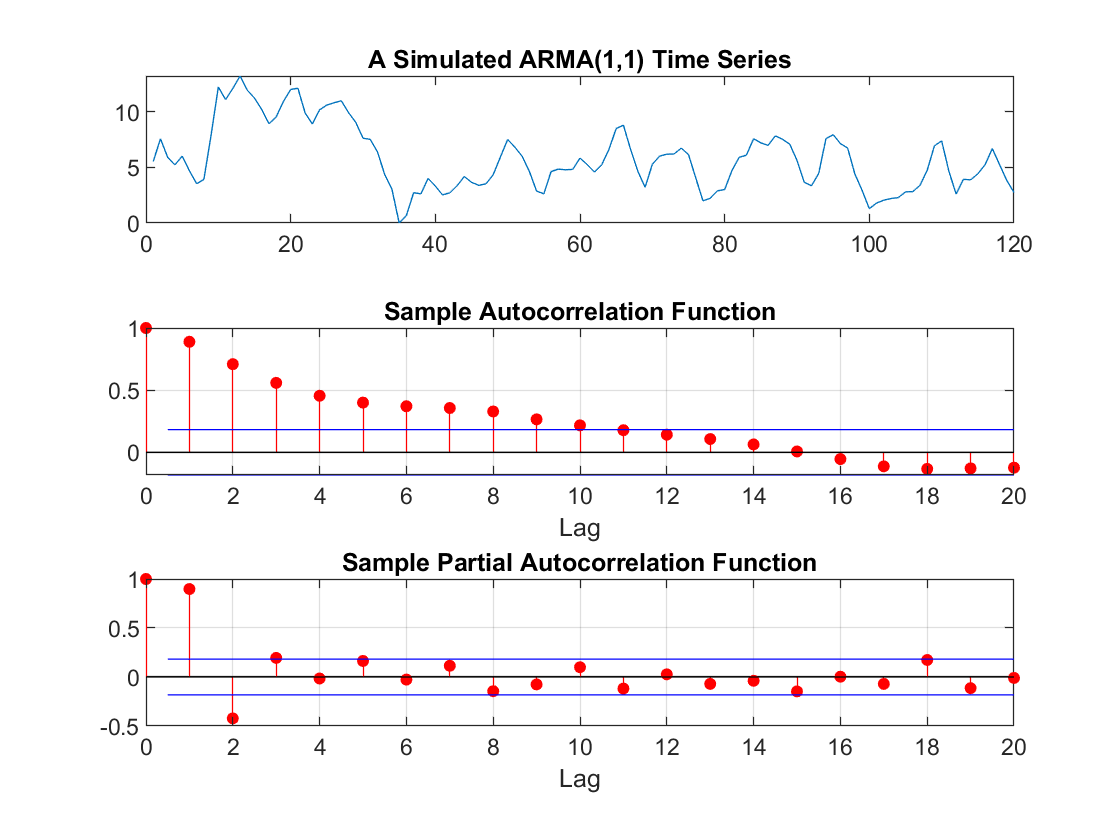

%%%%%%%%  an example of forecasting for a ARMA(1,1) process %%%%

% define a ARMA process used for simulation: x_t=1+0.8x_{t-1}+w_t+0.6*w_{t-1}, where w_t\tilde N(0,1)
phi1=0.8;
theta1=0.6;
Mdl_arma = arima('Constant',1,'AR',{phi1},'ARLags',1,'MA',{theta1},'MALags',1,'Variance',1);


%   simulate a time series
rng(0); % for reproducibility
T=120;
arma_ts=simulate(Mdl_arma,T);

%   generate sample ACF and PACF plots along with the time series
subplot(3,1,1)
plot(arma_ts)
title('A Simulated ARMA(1,1) Time Series');
subplot(3,1,2)
autocorr(arma_ts)
ylabel([])
subplot(3,1,3)
parcorr(arma_ts)
ylabel([])
%   let's try use information criteria to identify the model structure
%   we'll fit the original time series to four different models:
%   AR(1),AR(2), MA(1), MA(2), ARMA(1,1), ARMA(2,1), ARMA(1,2),ARMA(2,2)
%   and choose the best one based on information criteria (AIC and BIC)
EstMdl1 = arima('ARLags',1);
EstMdl2 = arima('ARLags',1:2);
EstMdl3 = arima('MALags',1);
EstMdl4 = arima('MALags',1:2);
EstMdl5 = arima('ARLags',1,'MALags',1); % this is the correct model
EstMdl6 = arima('ARLags',1:2,'MALags',1);
EstMdl7 = arima('ARLags',1,'MALags',1:2);

aic =   408.0127
  386.0104
  476.8260
  426.8409
  381.7795
  383.4094
  383.7600
  376.2279


bic =   416.3752
  397.1603
  485.1885
  437.9909
  392.9295
  397.3468
  397.6974
  392.9528


EstMdl8 = arima('ARLags',1:2,'MALags',1:2);


 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     1.0197       0.39935         2.5535        0.010666
    AR{1}         0.813      0.061321         13.258        4.05e-40
    MA{1}       0.55496       0.08317         6.6726      2.5133e-11
    Variance     1.3191       0.16119         8.1835      2.7564e-16



MyEstMdl =   arima with properties:

     Description: "ARIMA(1,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 1
        Constant: 1.01972
              AR: {0.812998} at lag [1]
             SAR: {}
              MA: {0.554956} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.3191


% Preallocate loglikelihood vector

Mdl_arma =   arima with properties:

     Description: "ARIMA(1,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 1
        Constant: 1
              AR: {0.8} at lag [1]
             SAR: {}
              MA: {0.6} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1

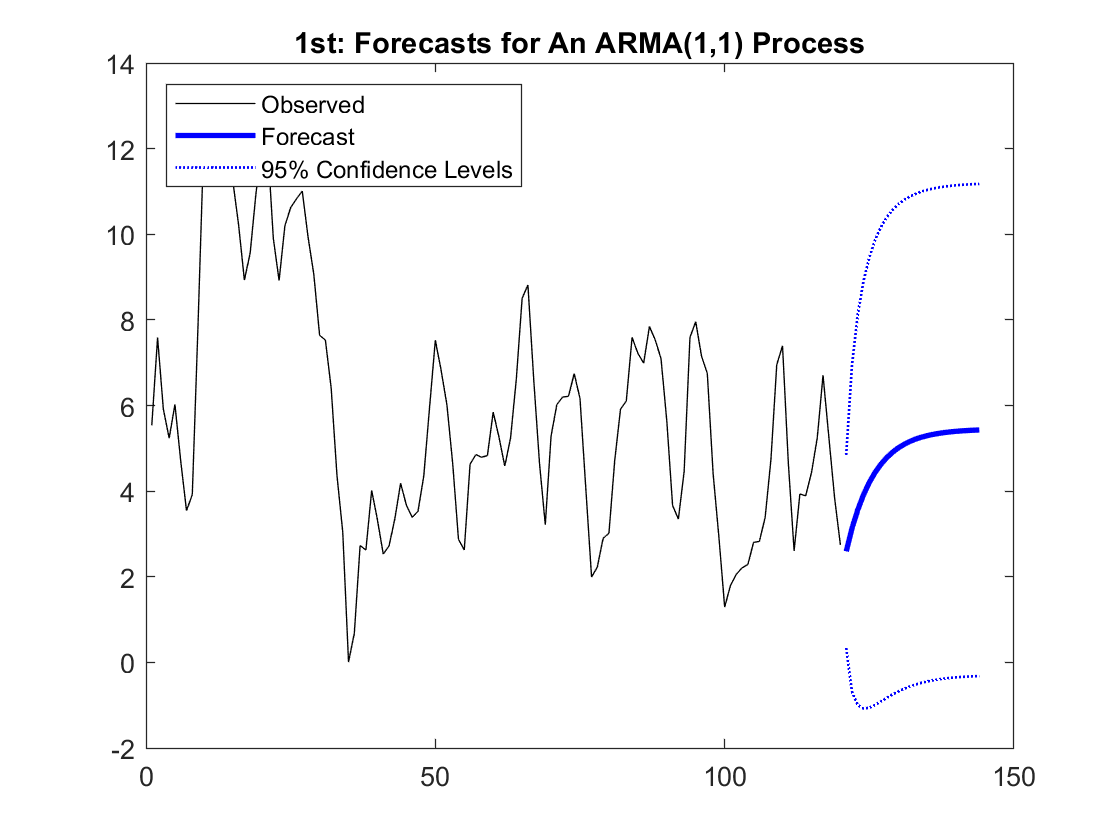

logL = zeros(8,1); 
[~,~,logL(1)] = estimate(EstMdl1,arma_ts,'Display','off');
[~,~,logL(2)] = estimate(EstMdl2,arma_ts,'Display','off');
[~,~,logL(3)] = estimate(EstMdl3,arma_ts,'Display','off');
[~,~,logL(4)] = estimate(EstMdl4,arma_ts,'Display','off');
[~,~,logL(5)] = estimate(EstMdl5,arma_ts,'Display','off'); %ARMA(1,1)
[~,~,logL(6)] = estimate(EstMdl6,arma_ts,'Display','off');
[~,~,logL(7)] = estimate(EstMdl7,arma_ts,'Display','off');
[~,~,logL(8)] = estimate(EstMdl8,arma_ts,'Display','off');

%   information criteria
[aic,bic] = aicbic(logL, [3; 4; 3; 4; 4; 5; 5; 6], length(arma_ts)*ones(8,1))
%   re-estimate the mdoel
MyEstMdl= estimate(EstMdl5,arma_ts)
%   compared with the true model
Mdl_arma
%%%%%%%%%%%%%%%%
%   let's make forecast for the next 24 periods and record the standard
%   deviation of the forecast errors
K=24;

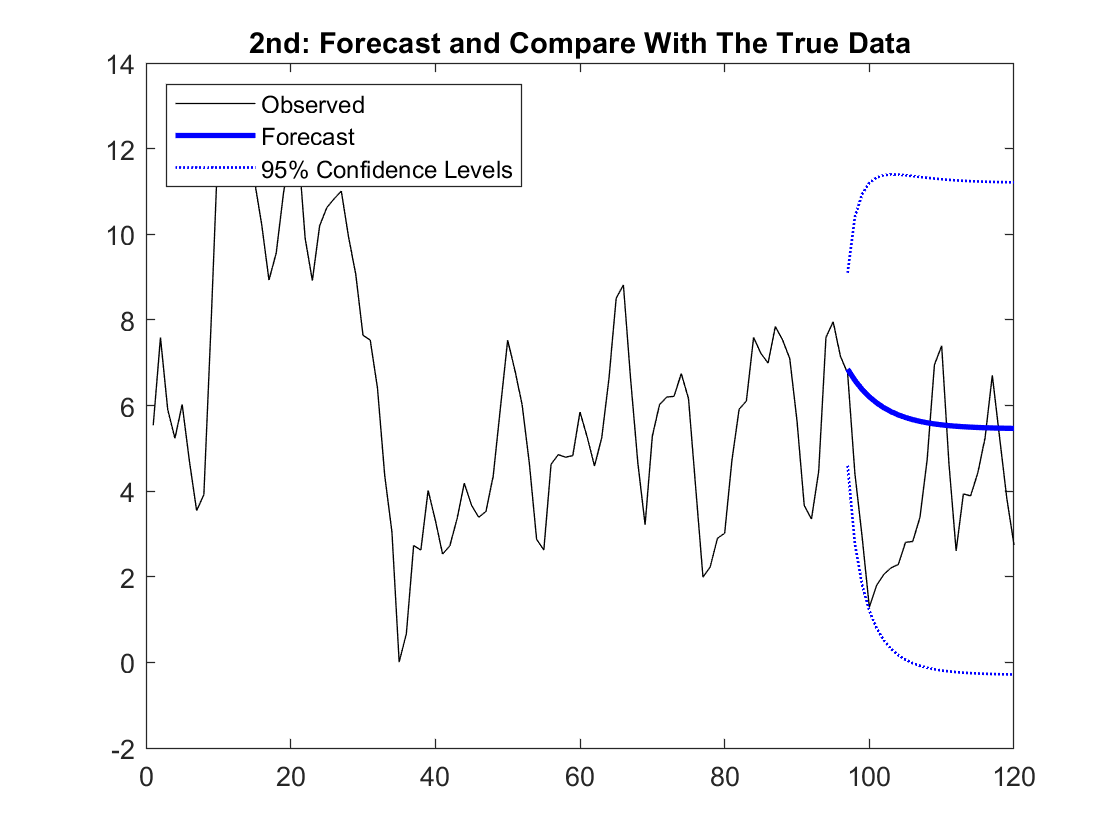


%   use the estimated model to make the forecasts
[Forecast_Vec,MSE_Vec] = forecast(MyEstMdl,K,'Y0',arma_ts);

%   make the plots
figure
h1 = plot(arma_ts,'k');
hold on

h2=plot(T+1:T+K,Forecast_Vec,'b','LineWidth',2);
h3=plot(T+1:T+K,Forecast_Vec + 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);
plot(T+1:T+K,Forecast_Vec - 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);

legend([h1 h2 h3],'Observed','Forecast','95% Confidence Levels','Location','NorthWest');
title('1st: Forecasts for An ARMA(1,1) Process')
hold off
%%%%%%%%%%%%%%%%%

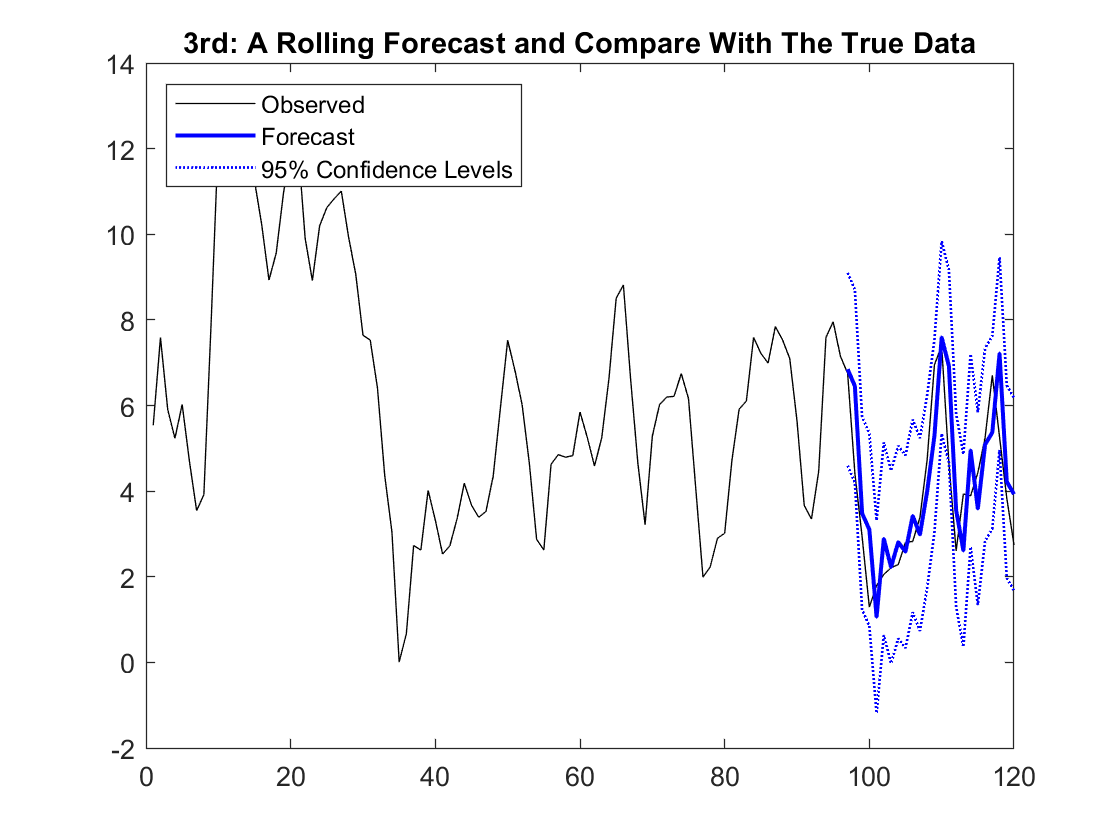

%   let's leave out the last 24 observations, and compare the forecasts
%   with the actual data
[Forecast_Vec,MSE_Vec] = forecast(MyEstMdl,K,'Y0',arma_ts(1:T-K));

%   make the plots
figure
h1 = plot(arma_ts,'k');
hold on

h2=plot(T-K+1:T,Forecast_Vec,'b','LineWidth',2);
h3=plot(T-K+1:T,Forecast_Vec + 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);
plot(T-K+1:T,Forecast_Vec - 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);
 
legend([h1 h2 h3],'Observed','Forecast','95% Confidence Levels','Location','NorthWest');
title('2nd: Forecast and Compare With The True Data')
hold off
%%%%%%%%%%%%%%%%%
%   let's make the forecast for the last K points on a rolling basis
Forecast_Vec=nan(K,1);
MSE_Vec=nan(K,1);

%   let's only look back past 50 data points
lb_pt=50;

%   run the rolling basis forecast one step ahead each time
for t=1:K

    [Forecast_Vec(t),MSE_Vec(t)] = forecast(MyEstMdl,1,'Y0',arma_ts(max(1,T-K-lb_pt+t):T-K+t-1));
end


%   make the plots
figure
h1 = plot(arma_ts,'k');
hold on

h2=plot(T-K+1:T,Forecast_Vec,'b','LineWidth',1.5);
h3=plot(T-K+1:T,Forecast_Vec + 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);
plot(T-K+1:T,Forecast_Vec - 1.96*sqrt(MSE_Vec),'b:','LineWidth',1);
 
legend([h1 h2 h3],'Observed','Forecast','95% Confidence Levels','Location','NorthWest');
title('3rd: A Rolling Forecast and Compare With The True Data')
hold off